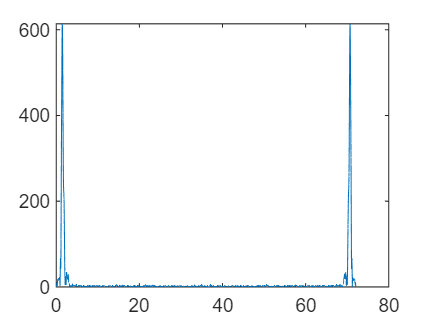

clear all; clc;
%-----------------------------------------------------------------------------------------------------
% 生成白光干涉信号
%显示光谱信息
format long
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency = (spectrum{:,1})';
spectrum_intensity = (spectrum{:,2})';
%disp("全部光谱信息");
plot(spectrum_frequency,spectrum_intensity)

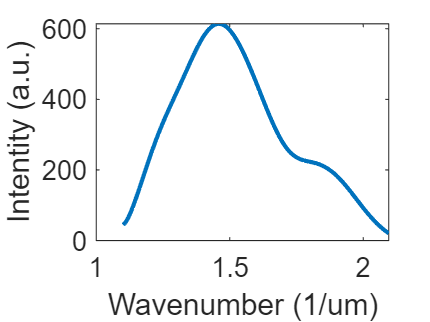

%找出探测器对应的光谱，这里假设是1.1-2.1
[~, indix_min] = min(abs(spectrum_frequency-1.1));
[~, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency = spectrum_frequency(indix_min:indix_max);
spectrum_intensity = spectrum_intensity(indix_min:indix_max);
%disp("需要的光谱信息");
plot(spectrum_frequency,spectrum_intensity,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Intentity (a.u.)')
ax = gca;
ax.FontSize = 13;

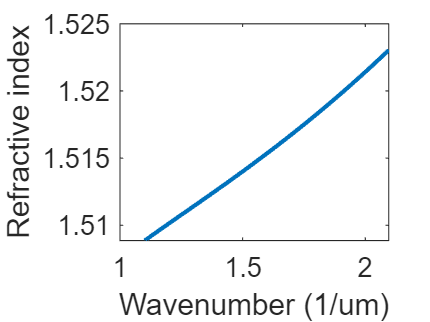


%生成白光干涉信号
z0 = 30;    %单位为微米
%加入色散
%色散公式
lambda = 1./spectrum_frequency;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./(lambda.^2-103.560653)+...
        (0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));
%折射率曲线
%disp("折射率曲线");
plot(spectrum_frequency,index,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Refractive index')
ax = gca;
ax.FontSize = 13;

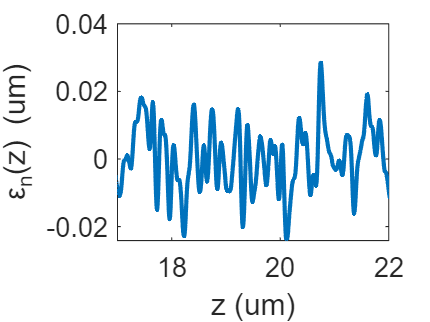

%色散
lEpsilon = 20; %单位为微米
N = 4000;
z = 0:40/4000:(N-1)*(40/4000);
interference_signal = zeros(1,length(z));
noise = gnoise(0,0.01,N);
% noise = normrnd(0,0.02,1,N);
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*spectrum_frequency+...
        4*pi*(index-1).*spectrum_frequency*lEpsilon));
end
plot(z,noise,'LineWidth',2);
xlim([17 22])
xlabel('z (um)') 
ylabel('{ε_n(z)} (um)')
ax = gca;
ax.FontSize = 13;

std(noise,0,2)

ans =    0.010000000000000


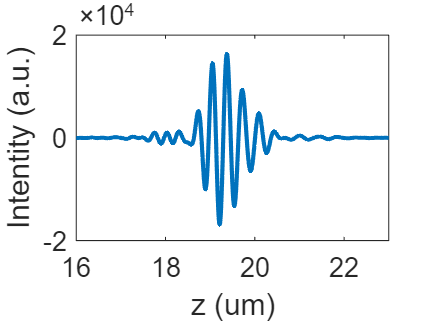


%-----------------------------------------------------------------------------------------------------
%傅里叶变换
%对白光干涉信号进行傅里叶变换,由于直流项的存在，补零操作会导致频域震荡。
%滤除直流项
interference_signal = interference_signal-mean(interference_signal);
plot(z,interference_signal,'LineWidth',2);
xlabel('z (um)') 
ylabel('Intentity (a.u.)')
xlim([16,23])
ax = gca;
ax.FontSize = 13;

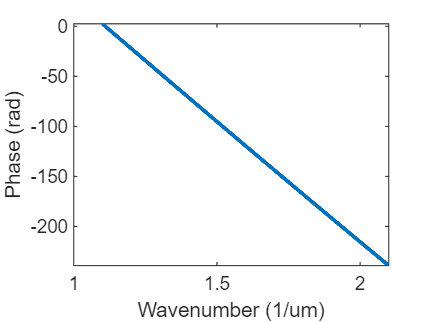

Nftt = 2^18;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(40/4000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
abs_fis = abs(f_interference_signal(1:Nftt/2+1));
ang_fis = angle(f_interference_signal(1:Nftt/2+1));
ang_fis = unwrap(ang_fis);
%对应频率1.1-2.1
[~, indix_min] = min(abs(sigma-1.1));
[~, indix_max] = min(abs(sigma-2.1));
plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Phase (rad)')

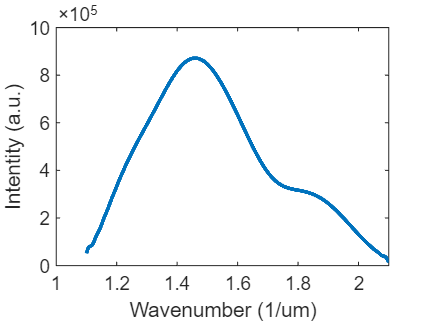

% ang_fis = ang_fis+4*pi*z0*sigma;

plot(sigma(indix_min:indix_max),abs_fis(indix_min:indix_max),'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Intentity (a.u.)')


plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Phase (rad)')

p = polyfit(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),1)

p = 	1.0e+00 *

 -241.7088  267.6297


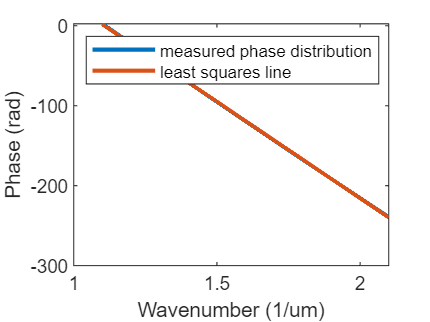

linear_fit = polyval(p,sigma(indix_min:indix_max));
nonlinear_fit = ang_fis(indix_min:indix_max) - linear_fit;
hold on
plot(sigma(indix_min:indix_max),linear_fit,'LineWidth',2);
hold off
legend('measured phase distribution','least squares line','Location','northwest')

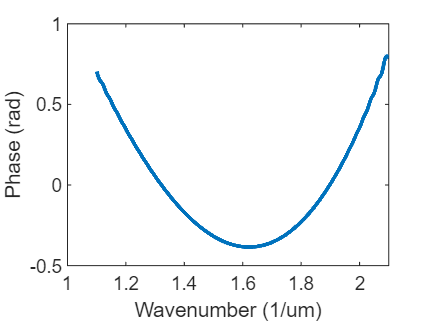


plot(sigma(indix_min:indix_max),nonlinear_fit,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Phase (rad)')

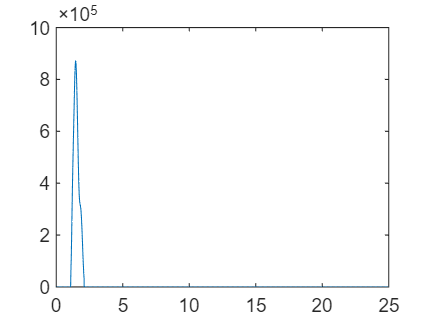


%-----------------------------------------------------------------------------------------------------
%傅里叶逆变换求z0
%正频域部分信号F(sigma)。
windowf = zeros(1,length(sigma));
windowf(indix_min:indix_max) = 1;
[I_sigma,n] = sigmult(abs_fis,1:length(abs_fis),windowf,1:length(windowf));
plot(sigma,I_sigma)

% I_sigma = abs_fis(indix_min:indix_max);
% P_sigma = polyval(p,sigma);
P_sigma = p(1)*sigma+p(2);
[P_sigma,~] = sigmult(P_sigma,1:length(P_sigma),windowf,1:length(windowf));
F_sigma = I_sigma.*exp(1i*P_sigma);
%计算加权平均波长
%lambdaA：加权平均波长
%powerTotal：总的波数振幅相加
%-----------------------------------
I_sigma1 = abs_fis(indix_min:indix_max);
sigma1 = sigma(indix_min:indix_max);
powerTotal = sum(I_sigma1);
power = sum(I_sigma1.*sigma1);
lambdaA = powerTotal/power

lambdaA =    0.656580169377717


%-----------------------------------
%逆傅里叶变换
Nifft = 2^20;
interference_signal1 = ifft(F_sigma,Nifft);
deltaSigma = (sigma(end)-sigma(1))/(length(sigma)-1);
deltaZ = 1/(2*Nifft*deltaSigma);
zData = (1:Nifft)*deltaZ;
intensity = abs(interference_signal1);
phase = angle(interference_signal1);
[~,index3]= max(intensity);
za1 = zData(index3);
%-----------------------------------
[~,indexend] = min(abs(zData-(za1+0.5)));
[~,indexstart] = min(abs(zData-(za1-0.5)));
unwrapZend = zData(indexend);
unwrapZ_1 = zData(indexstart);
unwrapN1 = index3;
unwrapNe = find(zData==unwrapZend);
unwrapN_1 = find(zData==unwrapZ_1);
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index3);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
indexP = find(phase1>0);
indexN = find(phase1<0);
[phaseP,indexZP]= min(phase1(indexP));
[phaseN,indexZN]= max(phase1(indexN));
zData0P = zData1(indexP(indexZP));
zData0N = zData1(indexN(indexZN));
%-----------------------------------
%计算结果
a1 = p(1)+4*pi*z0;
a0 = wrapToPi(p(2))

a0 =   -2.547265335426989


za=z0-(a1/(4*pi))

za =   19.234571665335835


zp=z0-((a1+a0*lambdaA)/(4*pi))

zp =   19.367663705727637


if za<0 && zp<0
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N-zData(end)
za1 = za1-zData(end)
zData = zData - zData(end);
else
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N
za1
end

zp1 =   19.370340725253218


za1 =   19.237500000000001


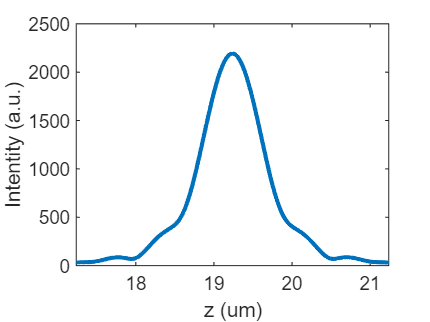

plot(zData,intensity,'LineWidth',2);xlim([zData(index3)-2 zData(index3)+2]);
xlabel('z (um)') 
ylabel('Intentity (a.u.)')

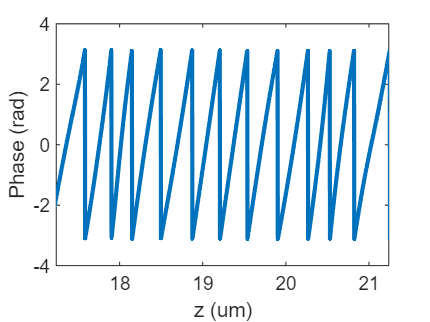

plot(zData,phase,'LineWidth',2);xlim([zData(index3)-2 zData(index3)+2]);
xlabel('z (um)') 
ylabel('Phase (rad)')

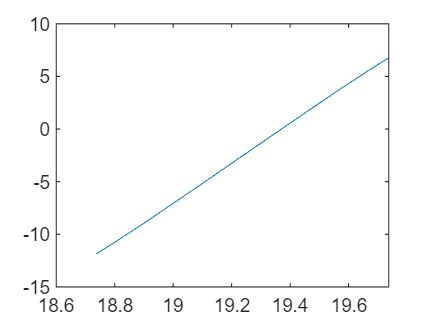

plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));

% zadiff = za1-za
% zpdiff = zp1-zp
z01 = za1+(a1/(4*pi))

z01 =   30.002928334664166


z02 = zp1+((a1+a0*lambdaA)/(4*pi))

z02 =   30.002677019525581


diff1 = z01-z0

diff1 =    0.002928334664166


diff2 = z02-z0

diff2 =    0.002677019525581


function noise = gnoise(mean1,std1,N)
MU=mean1;
SIGMA=std1;
noise(1:N)=0;
corn=15;%%%180
han=hanning(corn);%Extension=60;
han=han';
NOISE1=normrnd(MU,SIGMA,1,N+corn);%NOISE2=normrnd(MU,SIGMA,1,N+Extension);
for no=1:N
ii=no;
noise(ii)=sum(han.*NOISE1(ii:ii+corn-1))/corn;%%%%100/24差不多4um不懂含义。。。。
end
noise1 = noise(1:N);
noise1_mean = mean(noise1);
noise1_std = std(noise1);
noise = (noise1-noise1_mean)./noise1_std*SIGMA;
% noise_mean = mean(noise);
% noise_std = std(noise);
end

function [y,n] = sigmult(x1,n1,x2,n2)
%implements y(n) = x1(n) * x2(n);
%-----------------------------------
%[y,n]=siggadd(x1,n1,x2,n2)
%x1=first sequence over n1
%x2=first sequence over n1
n = min(min(n1),min(n2)):max(max(n1),max(n2));
y1 = zeros(1,length(n));
y2 = y1;
y1(find((n>=min(n1))&(n<=max(n1))==1))=x1;
y2(find((n>=min(n2))&(n<=max(n2))==1))=x2;
y=y1.*y2;
end
